## Method

Here we will describe the approach to model, simulate, and analyze the ice-cream dispensing robot. In this section, we will discuss the derivation of forward kinematics, construction of the Jacobian for singularity analysis, derive the algorithm for numerical inverse kinematics, and discuss our approach for trajectory planning.

### Forward Kinematics

Forward kinematics refers to the process of calculating the position and orientation of a robot’s end-effector (or any desired final frame) with respect to a base frame. This is useful in order to keep track of the robot’s end-effector given a set of input joint angles or displacements. Here we follow the Denavit-Hartenberg (DH) convention for forward kinematic derivation. The figure below displays the robot and the assigned frames. 

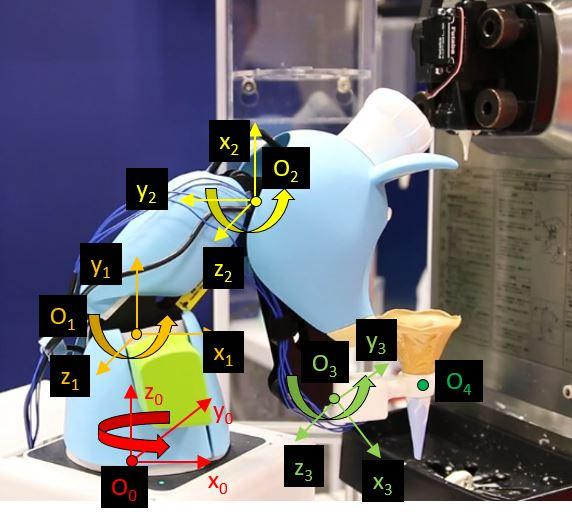

*Figure XX: The robot arm in action with assigned DH frames*

This is a RRRR style manipulator. Below we show the frames and joint angles in home configuration. Note that $O_3$ is at an angle $\gamma$ from the vertical with respect to $O_2$. 

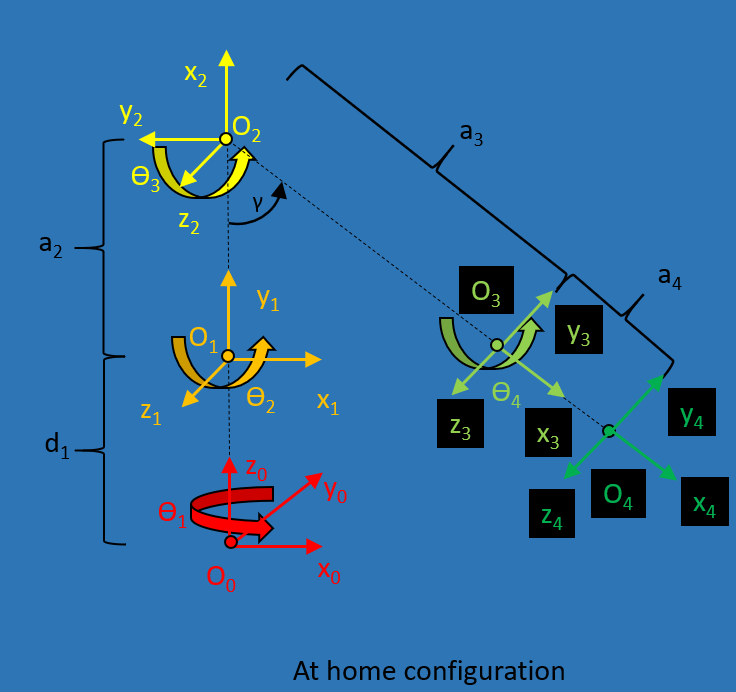

*Figure XX: DH Convention assigned frames*

We first explain how the frames were chosen using the DH convention described in pages 86-87 in [Robot Modeling and control ###]:

- There are 4 revolute joints and so the z-axes are positioned on the axis of revolutions for these 4 joints ($\left.z_0 ,z_1 ,z_2 ,z_3 \right)\ldotp$

- We establish the base frame ($\left.O_0 \right)$ at ground level and use a right-hand coordinate system and arbitrarily choose direction of $x_0 ,y_0$ for convenience.

- To find the origin of $O_1$ we find the intersection of $z_0$ and $z_1$. To find the origin of $O_2$, we follow the normal between the parallel axes $z_1$ and $z_2$. To find $O_3$, we similarly follow the normal between the parallel axes $z_2$ and $z_3$. $O_4$ is attached to the end-effector. The orientation of the end-effector is identical to $O_3$ (in home config).  

- To find the x-axis of Frame 1, we choose $x_1$ to be perpendicular to $z_0$ and attached to $O_1$. Similarly, to find the x-axis of Frame 2, we choose $x_2$ to be perpendicular to $z_1$ and attached to $O_2$. $x_3$ is along the common normal between $z_2$ and $z_3$ as per DH convention. 

- We find $y_1$ and $y_2$ to complete the right-hand coordinate frames.

We can then proceed with the following steps to obtain the homogeneous transformation matrix that describes the end-effector position and orientation with respect to the base frame:

- Create the DH parameter table, described below.

- Substitute the values from DH parameter table into Equation 3.10 in [1], described below.

- Construct $T_4^0 =A_1 A_2 A_3 A_4$.

To construct the DH parameter value, we list what each parameter describes:

- $\alpha_i \;$: rotate $x_i$ so that $z_{i-1}$ aligns $z_i$

- $\theta_i \;$: rotate $z_{i-1} \;$so that $x_{i-1}$ aligns $x_i$

- $d_i$: displacement along $z_{i-1}$ from $O_{i-1}$ to $O_i$

- $a_i$: displacement along $x_i$ from $O_{i-1}$ to $O_i$

First we look at $a_i$. For link 1, there is no displacement from $O_0$ to $O_1$ along $x_0$ so $a_1 =0$. From $O_1$ to $O_2$ along $x_1$, the displacement is  $a_2$. Similarly, from $O_2$ to $O_3$ along $x_2$, the displacement is $a_3$. Lastly, from $O_3$ to $O_4$ along $x_3$, the displacement is $a_4$.

Now we look at $\alpha_i$. For link 1, to align $z_0$ and $z_1$ about $x_1$ requires 90 deg rotation counter-clockwise (positive rotation). $z_1 ,z_2 ,z_3$ are all parallel, so $\alpha_2 =\alpha_3 =\alpha_4 =0$.

Now we look at $d_i$. For link 1, the displacement from $O_0$ to $O_1$ along $z_0$ is $d_1$. There is no displacement from $O_1$ to $O_2$ along $z_1$ or from $O_2$ to $O_3$ along $z_2$ or from $O_3$ to $O_4$ along $z_3 \;$so $d_2 =d_3 =d_4 =0$.

Lastly, since we aligned the rotation axes of all 3 revolute joints with $z_i$ for i=1,2,3 this corresponds to $\theta_1 ,\theta_2 ,\theta_3$. However, there is a positive rotation of  $\frac{\pi }{2}$  to align $x_1$ and $x_2$ and a negative rotation of  $\frac{\pi }{2}+\gamma \;$ to align $x_2$ and $x_3$. The full DH parameter list is summarized in the table below:

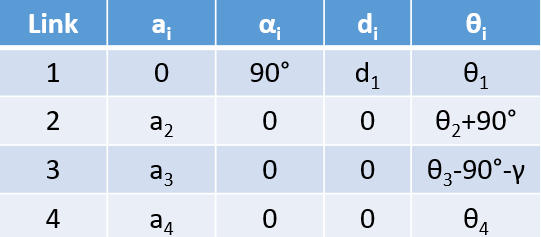

We use the values from DH parameter table above in the general form of the homogeneous transformation matrix $A_i$, given in Eq. 3.10 in [1]:


$$A_i =\left\lbrack \begin{array}{cccc}
c\theta_i  & -s\theta_i c\alpha_i  & s\theta_i s\alpha_i  & a_i c\theta_i \\
s\theta_i \; & c\theta_i c\alpha_i  & -c\theta_i s\alpha_i  & a_i s\theta_i \\
0 & s\alpha_i \; & c\alpha_i \; & d_i \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


Substituting the values for each link leads to:


$$A_1 =\left\lbrack \begin{array}{cccc}
c\theta_1  & 0 & s\theta_1  & 0\\
s\theta_1 \; & 0 & -c\theta_1  & 0\\
0 & 1 & 0\; & d_1 \\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_2 =\left\lbrack \begin{array}{cccc}
c\left(\theta_2 +\frac{\pi }{2}\right) & -s\left(\theta_2 +\frac{\pi }{2}\right) & 0 & a_2 c\left(\theta_2 +\frac{\pi }{2}\right)\\
s\left(\theta_2 +\frac{\pi }{2}\right)\; & c\left(\theta_2 +\frac{\pi }{2}\right) & 0 & a_2 s\left(\theta_2 +\frac{\pi }{2}\right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$
 


$$A_3 =\left\lbrack \begin{array}{cccc}
c\left(\theta_3 -\frac{\pi }{2}-\gamma \right) & -s\left(\theta_3 -\frac{\pi }{2}-\gamma \right) & 0 & a_3 c\left(\theta_3 -\frac{\pi }{2}-\gamma \right)\\
s\left(\theta_3 -\frac{\pi }{2}-\gamma \right)\; & c\left(\theta_3 -\frac{\pi }{2}-\gamma \right) & 0 & a_3 s\left(\theta_3 -\frac{\pi }{2}-\gamma \right)\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$



$$A_4 =\left\lbrack \begin{array}{cccc}
c\theta_4  & -s\theta_4  & 0 & a_4 c\theta_4 \\
s\theta_4  & c\theta_4  & 0 & a_4 s\theta_4 \\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$$


We can then construct the homogeneous transformation matrix that describes the position and orientation of the end-effector frame to the base frame by composing the transformation matrices between each frame as follows:

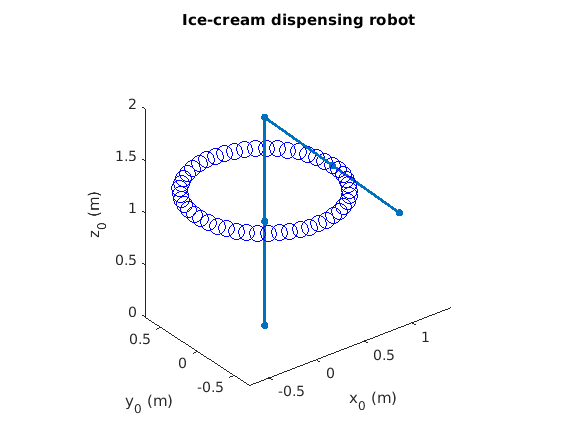

clear all; close
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;
intervals = 50;
theta1_vec = linspace(0,2*pi,intervals);
theta2_vec = linspace(0,0,intervals); 
theta3_vec = linspace(0,0,intervals);
theta4_vec = linspace(0,0,intervals);

for i=1:length(theta1_vec)
    a_vec = [0, a2, a3, a4]; 
    alpha_vec = [pi/2, 0, 0, 0]; 
    d_vec = [d1, 0, 0, 0]; 
    theta1=theta1_vec(i); theta2=theta2_vec(i); theta3=theta3_vec(i); theta4=theta4_vec(i);
    theta_vec = [theta1, theta2 + pi/2, theta3 - pi/2 - gamma, theta4];
    [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec); 
    plot_link(P_vec,i,intervals);
end
xlabel('x_0 (m)'); ylabel('y_0 (m)'); zlabel('z_0 (m)'); title('Ice-cream dispensing robot')

### Jacobian and Singularities

From the DH table that we've generated for the robotic arm, we can generate the Jacobian for the arm. Once we have the Jacobian, we can determine both end effector velocities (linear and angular) as well as try to find if any singularities exist within the arm design.

The Jacobian of our arm will be a 6x4 matrix - 3 rows for each of the linear and angular velocities, and then a column for each joint on the robotic arm. Typically, the equations for the Jacobian of a given robotic joint are, for prismatic joints:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} \\
0
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for a prismatic joint*

...and for revolute joints, the Jacobian is found through:


$$J_i =\left\lbrack \begin{array}{c}
z_{i-1} x\left(o_n -o_{i-1} \right)\\
z_{i-1} 
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for a revolute joint*

Our arm is a four axis robot with each joint being a revolute joint. As such, the equation for the Jacobian that we'll use is:


$$J=\left\lbrack \begin{array}{cccc}
z_0 x\left(o_4 -o_0 \right) & z_1 x\left(o_4 -o_1 \right) & z_2 x\left(o_4 -o_2 \right) & z_3 x\left(o_4 -o_3 \right)\\
z_0  & z_1  & z_2  & z_3 
\end{array}\right\rbrack$$


*Equation XX: The Jacobian for our robot arm*

When a Jacobian's determinant is equal to 0, the Jacobian is of a lower rank than the number of joints in the robot. As such, we have achieved a singularity. We will be making use of the $\det \left(J\right)=0$ to prove that we have found a singularity throughout this paper.

Once we have explored the Jacobian symbollically, we will use numerical computation methods to explore the singularities for the ice cream robot arm. Many robot arms have three common sources of singularities. A **wrist singularity**, an **elbow singularity**, and an **overhead** **singularity** when the tool path crosses above the arm's head. For our applications, the overhead singularity will not be explored as our use case prevents any movement of the arm above the head.

The **wrist singularity** occurs when a wrist joint has its base frame and secondary frame - in our case $\theta_3$ and $\theta_4$ are co-linear - when $\theta_4 ==0\;\textrm{or}\;\theta_4 ==\pi$.

The **elbow singularity** occurs when the elbow's orientation matches a value based on the geometry of the robot - specifically when the angle of the elbow matches the arctan of the elbow's distance between $\theta_2$ and $\theta_3$. What that angle is we will not know until we perform numerical anaylsis of the Jacobian.

### Inverse Kinematics

Inverse kinematics (IK) is the oposite of forward kinematics (FK). In IK the desired end effector position is known; therefore the goal is to calculate the joint variables necessary to reach that position. There are several methods known for solving the IK of a robotic system. In this assignmnet we will be exploring two of these methods: the geometric approach and the numerical approach. THe results of these two methods then be compared. 

**Numerical IK**

I will first begin to discuss the numerical approach that was taken to calculate the inverse kinematics of the system. Numerical IK, iteratively tries to solve for the best matching solutions, or joint values, with in a given error margin for the given desired  end effector position. This method is ore computationally expensive than the geomatric approach but it is handy and less human expensive for complex systems where a geometric approach would be too difficult. 

To begin the numerical approach at solving for the inverse kinematics of the ice cream serving robot system, I first  extracted the upper half of the jacobian, Jv , the part relating to the linear velocity of the end effector. I also extracted the position column, pe,  from the homogeneous transformation matrix (HTM) describing relating the end effector frame to the base frame of the robot, T04, because this would allow me to calcualte the forward kinematics in order to solve for the position vector corresponding to the joint angles that are being optimized iteratively.  I also provided an initial geuss, q0, for the joint angles that will solved numerically and for the first iteration i set the  calcualted instant angles,qq, equal to the initial guess.  I also calcualte for the error between the desired position requestion and the position vector calcualted by the program.

pe = expand(T04(1:3,4)); % position vector 
q0 = [105;105; 105;105]; % initial guess 
pd = [-0.5; 0.5; 1]; % desired position
qq = q0; % the joint variables calculated for the iteration
f_pe = matlabFunction(pe); % made the position vector a function
pei = f_pe(qq(1),qq(2), qq(3), qq(4)); %solve for the current iteration's position vector
error = pd - pei ; % calcualted error, want to minimize discrepency between desired and calculated values
f_Jv = matlabFunction(Jv); % make a function out of the jacobian function

Figure X- Snippet of the inverse kinematics code where i define all of the function and initial guess,

For the iterative poriton of the code, I have a while loop that checks for the error values, describing the difference between the desired position vector and the position vector calcualted in the current iteration. The while loop will stop once the error is below 0.2. First, the jacobian is calcualted for the current joitn values calculated by the loop. Then the inverse of the the jacovian is taken and multiplied by the error calcualted in order to obtain the the step factor, or delta_q of the loop. Next, this step factor is added to the current joint value calcualtion. The position vector corresponding to these new joint variables is calculated and compared to the desired position vector, in order to calcualte the error. if the errro is still above the threshhold, then the loop will continue, if it is not then it will terminate.

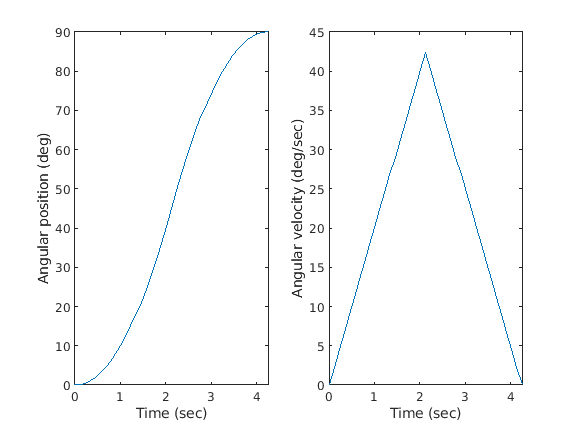

while norm(error) > 0.2 
    Jv_q = f_Jv (1, 1, 1,qq(1),qq(2), qq(3), qq(4));
    delta_q= pinv(Jv_q)* error ;
    qq = qq + delta_q
    pei = f_pe(qq(1),qq(2), qq(3), qq(4));
    error = pd - pei;
    norm(error)
end
qq 

pei 

Now that the code in order to calcualte for the inverse kinematics of the system has been developed, the joint positions corresponding to certain desired positions can be calulated numerically without much arithmatic. 

**Geometric IK**

I will now be discussing the geometric approach taken to calculate the inverse kinematics of the system. Figure X, below depicts the geometric shapes analyzed in order to obtain the vlaue of the first joint variable. 

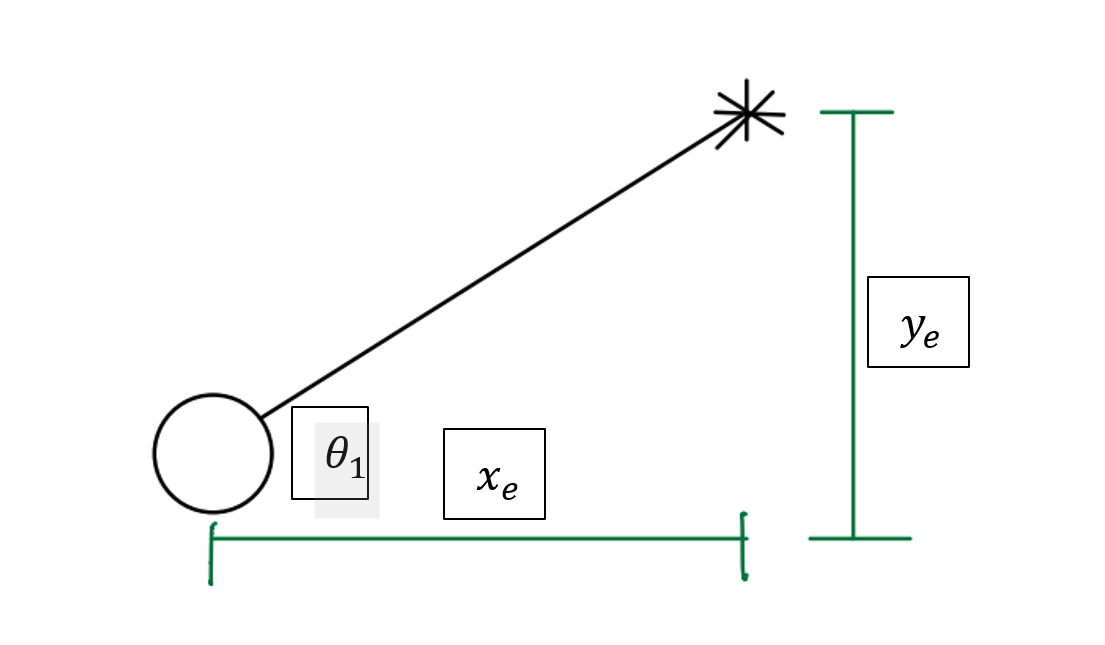

Figure X  - Geometrics shapes and variables used to calculate the value of the first joint angle.

Solving for this variable was very simple and straight forward, as it could be solved with just one simple trigonometry calculation, see equation below. 


$$\theta_1 =\textrm{atan2}\;\left(y_e ,x_e \right)$$
                                

Solving for the other joint variables was not as straight forward as solving for the first, as they involved more geometric equations. Figure x, below show the diagrams used to solve for the second, third and fourth joint variables .

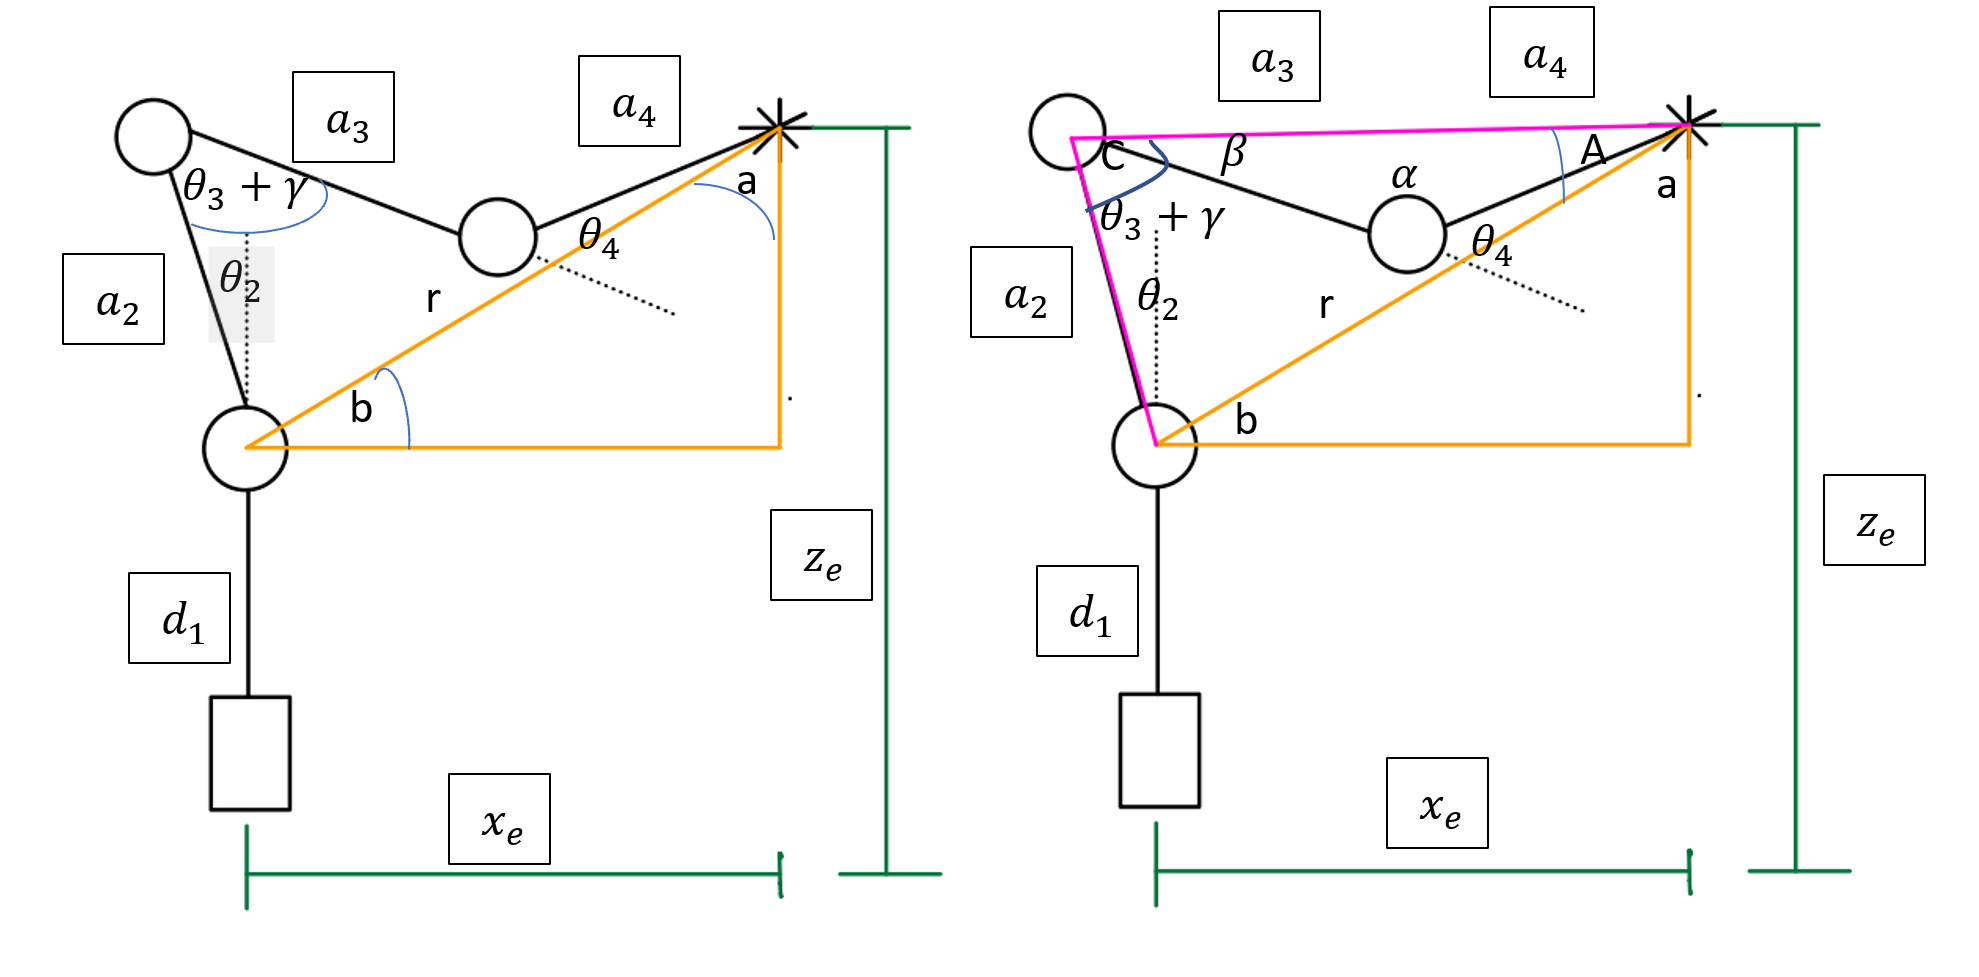

Figure X - Diagram of the geometric shapes analyzed to calculate for for the second, third and fourth joint variables 

To solve for the second joint varible, I first assumed that the second link forms a right angle with the resultant, r,  from the center of the second joint to the end effector position. I made this assumption because in the video of the ice cream serving robot, which inspired this project, the second link always seems to align normally to the resultant, this ensures that the ice cream fall smoothly and directly in ot the cone. that being said, i first calculated angle b, shown in the diagrams, by using the the atan2 function, I then subtracted the angle b from 90 degrees and was able to obtain the second joint varible equation, see below. 


$$b=\mathrm{atan2}\;\left({\left(z_e -d_1 \right),x}_e \right)$$
 


$$\theta_2 =90-b$$


To solve for the third joint angle variable , I first needed to solve for a few other parameters. First  I solved for the resultant distance, r,  between the middle of the second joint and the end effector using pythagorean theorem. After this I used pythagorean theorem again to solve for P, the distance between the third joint and the the end effector. After this I used the law of cosines twice in order to obtain angles C and $\beta$.  Ithen used these terms to solve the third joint angle algebraically. 


$$r=\sqrt{{x_e }^2 +{\left(z_e -d_1 \right)}^2 \;}$$



$$P=\;$$

$$\sqrt{{a_2 }^2 +r^2 \;}$$



$$C=\mathrm{acos}\left(\frac{{a_2 }^2 +P^2 -r^2 }{2a_2 P}\right)$$


$\beta$= $\mathrm{acos}\left(\frac{{a_3 }^2 +P^2 -{a_4 }^2 }{2a_3 P}\right)$


$$\theta_3 =C-\left(\gamma +\beta \right)$$


Finally to solve for the fourth joitn varible, I first used the law of cosines to solve for the angle $\alpha$. Then I subtracted $\alpha$ from 180 to get the fourth joint angle, as they form 180 degree line together. 


$$\alpha$$

$$=\mathrm{acos}\left(\frac{{a_3 }^2 +{a_4 }^2 -P^2 }{2a_3 a_4 }\right)$$



$$\theta_4 =180-\;$$

$$=\mathrm{acos}\left(\frac{{a_3 }^2 +{a_4 }^2 -P^2 }{2a_3 a_4 }\right)$$


Now using these equations for the joint variables, the joint variables can now be calculated for any desired position. 

### Trajectory Planning

Here we will describe our approach to trajectory planning for the ice-cream dispensing robot arm. There are a maximum of 6 desired end-effector points: home, cone dispenser, flavor 1, flavor 2, flavor 3, and customer drop-off. Each cycle begins with the end-effector at the home config, then cone dispenser, a combination of flavors, customer drop-off, and then back at home. This simplifies our trajectory planning problem since some paths repeat every cycle. 

The steps for trajectory planning are given as follows:

- Use numerical inverse kinematics to find singularity-free joint angles that correspond to the end-effector at each of the 6 points.

- Generate a singularity-free minimum time trajectory from home to cone dispenser and from customer drop-off to home.

- Depending on customer choice of flavors, generate singularity-free minimum time trajectories from cone dispenser to first flavor, between flavors, and then to customer drop-off.

- Combine trajectories in correct order and execute motion.

- Repeat steps 3-4 for next cycle depending on customer input.

We use a minimum-time trajectory to optimize the cycle time. Given a constant acceleration, this specifies the shortest trajectory time by starting the trajectory at maximum acceleration ($+\alpha$) until an appropriate switching time, at which point we instantly switch to minimum acceleration ($-\alpha$). Since each trajectory requires zero velocity at the beginning and end, the switching time occurs at half the total trajectory time. Let $t_0$ be the start time and $t_f$ be the end time of the trajectory. We know from trajectory symmetry that the switching time $t_s =\frac{t_f -t_0 }{2}$. Let the velocity at the switching time be $V_s$ and for constant acceleration, we have $V_s =\alpha t_s$. Let $q_0$ and $q_f$ be the initial and final configuration. At the switching time, we have: $V_s =\frac{q_f -q_0 }{t_s }=\alpha t_s \;$. This leads to $t_s =\sqrt{\frac{q_f -q_0 }{\alpha }}$. 

We consider a simple example where we are asked to find a trajectory from home configuration $\theta_1 =0$ to a desired configuration $\theta_1 =\frac{\pi }{2}$ within 5 sec with a maximum joint angle acceleration $\alpha =20\;\frac{\deg }{s^2 }$. We can treat each joint motion as an independent trajectory, so this method can scale for other joints as well. The trajectory needs to be checked to ensure no singularities are crossed (described earlier, but not considered in this example). 

For $\theta_1$, $t_s =\sqrt{\frac{q_f -q_0 }{\alpha }}=\sqrt{\frac{\frac{\pi }{2}-0}{20}}=2\ldotp 12\;\sec$, which leads to $t_f =4\ldotp 24\;\sec$ (within our 5 sec specification). The angular velocity of joint 1 in the accelerating segment of the trajectory is simply given by $V_1 =\alpha t$, leading to joint angle equation of $\theta_1 =\frac{\alpha t^2 }{2}$. For the decelerating segment, the angular velocity of joint 1 is given by $V_1 =V_s -\alpha \left(t-t_s \right)=\alpha t_s -\alpha \left(t-t_s \right)=2\alpha t_s -\alpha t$. Integrating this with the appropriate initial condition leads to $\theta_1 =$$-\frac{\alpha t^2 }{2}+2\alpha t_s t^2 -\alpha t_s^2$. We can plot the angular position and velocity profiles below:

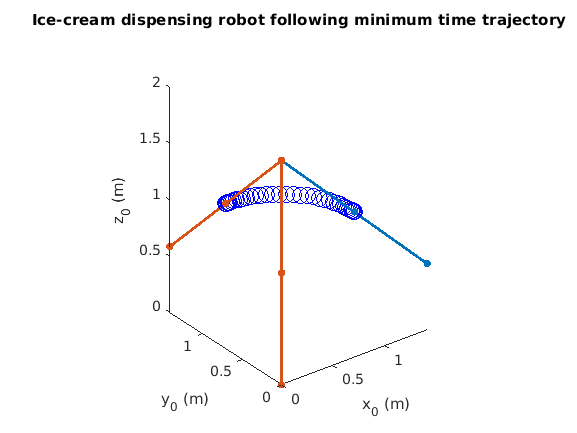

figure
qs=0; qf=pi/2; alpha=deg2rad(20);
ts=sqrt((qf-qs)/alpha);
interval=20;
t1=linspace(0,ts,interval);
t2=linspace(ts,2*ts,interval);
ang_pos1 = 0.5*alpha*t1.^2;
ang_pos2 = -0.5*alpha*t2.^2 + 2*alpha*ts*t2 - alpha*ts^2;
ang_vel1 = alpha*t1;
ang_vel2 = 2*alpha*ts - alpha*t2;
t=[t1,t2];
ang_pos=rad2deg([ang_pos1,ang_pos2]);
vel_pos=rad2deg([ang_vel1,ang_vel2]);

subplot(1,2,1)
plot(t,ang_pos); xlabel('Time (sec)'); ylabel('Angular position (deg)')
subplot(1,2,2)
plot(t,vel_pos); xlabel('Time (sec)'); ylabel('Angular velocity (deg/sec)')

The trajectory generated matches our desired specification. The velocity profile is piece-wise linear and changes slope at the switching time. The angular position accelerates and decelerates in a smooth motion. We can visualize $\theta_1$ in the ice-cream robot following this motion as follows:

figure
d1=1; a2=1; a3=1; a4=1; gamma=pi/4;
theta1_vec = deg2rad(ang_pos);
for i=1:length(theta1_vec)
    a_vec = [0, a2, a3, a4]; 
    alpha_vec = [pi/2, 0, 0, 0]; 
    d_vec = [d1, 0, 0, 0]; 
    theta1=theta1_vec(i); 
    theta_vec = [theta1, 0 + pi/2, 0 - pi/2 - gamma, 0];
    [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec); 
    plot_link(P_vec,i,length(theta1_vec));
end
xlabel('x_0 (m)'); ylabel('y_0 (m)'); zlabel('z_0 (m)'); title('Ice-cream dispensing robot following minimum time trajectory')

We can see the end-effector points are spaced tighter at the beginning and end and looser in the middle of the motion, indicating the accelerating and decelerating motion. 

## Results

### Functions

function [H, P_vec, All_H] = DHmatrix(a_vec,d_vec,alpha_vec,theta_vec)
% Author: Nithin Kumar
% Date: 3/18/2021
% This function calculates the homogeneous transformation matrix H using DH
% convention input parameters and outputs the final H^0_n, the position of all frames
% (P_vec), and all the H matrices.
H=eye(4);
P = [0;0;0;1];
P_vec = zeros(4,length(a_vec));
    for i=1:length(a_vec)
        a=a_vec(i); d=d_vec(i); alpha=alpha_vec(i); theta=theta_vec(i);
        H_tmp = [cos(theta), -sin(theta)*cos(alpha), sin(theta)*sin(alpha), a*cos(theta); ...
        sin(theta), cos(theta)*cos(alpha), -cos(theta)*sin(alpha), a*sin(theta); ...
        0, sin(alpha), cos(alpha), d; ...
        0, 0, 0, 1];
       
        H=H*H_tmp;
        All_H(:,:,i) = H;
        P_vec(1:4,i) = H*P;
    end
end

function plot_link(P_vec,current,end_condition)
% This function plots each link with input P_vec that describes the origin
% of each frame.
    A = [0 P_vec(1,:)];
    B = [0 P_vec(2,:)];
    C = [0 P_vec(3,:)];
    h1=plot3(A,B,C,'.-','MarkerSize',12,'LineWidth',2);
    hold on
    h2=plot3(P_vec(1,3),P_vec(2,3),P_vec(3,3),'bo','MarkerSize',12);
    axis equal
    pause(0.05)
    if current~=end_condition && current~=1
        delete(h1)
    end
    
end